clf;
clear;

Lena = imread("../materials/Lena.tif");
size(Lena)

ans =    256   256


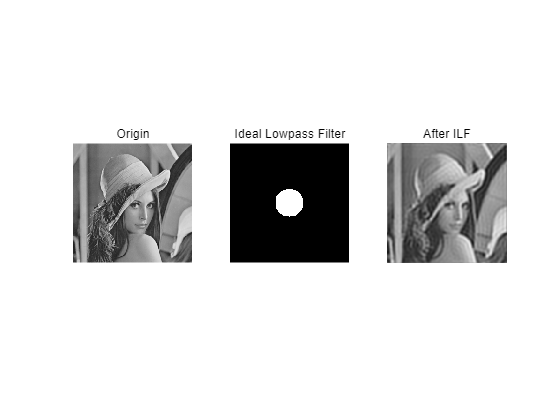


FFT_Lena = fftshift(fft2(im2double(im2gray(Lena))));

ILF_Filter = my_ILF(FFT_Lena);
ILF_Lena = im2uint8(real(ifft2(ifftshift(ILF_Filter))));
Butterworth_Filter = my_Butterworth(FFT_Lena,4); % 4th
Butterworth_Lena = im2uint8(real(ifft2(ifftshift(Butterworth_Filter))));

figure;
subplot(1,3,1);
imshow(Lena);title('Origin');
subplot(1,3,2);
imshow(log(abs(ILF_Filter)));title('Ideal Lowpass Filter');
subplot(1,3,3);
imshow(ILF_Lena);title('After ILF');

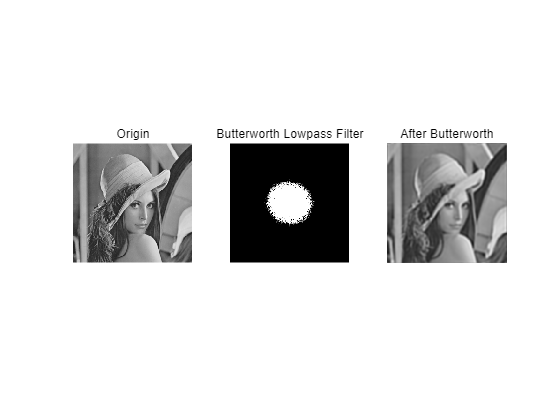


figure;
subplot(1,3,1);
imshow(Lena);title('Origin');
subplot(1,3,2);
imshow(log(abs(Butterworth_Filter)));title('Butterworth Lowpass Filter');
subplot(1,3,3);
imshow(Butterworth_Lena);title('After Butterworth');

function out = my_ILF(image) % ideal lowpass filter
    [M,N] = size(image);
    m = ceil(M/2);
    n = ceil(N/2);
    out = [M,N];

    D0 = 30;
    for i = 1:M 
        for j = 1:N
            distance = sqrt((i-m)^2+(j-n)^2);
            if distance <= D0
                h = 1;
            else
                h = 0;
            end
            out(i,j) = h*image(i,j);
        end
    end
end

function out = my_Butterworth(image, set) % Butterworth
    [M,N] = size(image);
    m = ceil(M/2);
    n = ceil(N/2);
    out = [M,N];

    D0 = 30;
    for i = 1:M
       for j = 1:N
           d = sqrt((i-m)^2+(j-n)^2);
           h = 1/(1+0.414*(d/D0)^(2*set));
           out(i,j)=h*image(i,j);
       end
    end
end